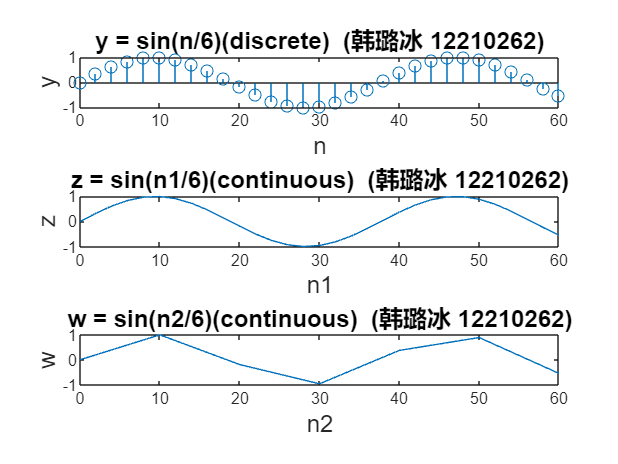

%1.3.2
figure
n = 0:2:60;
y = sin(n/6);
subplot(3,1,1)
stem(n,y)
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('y','FontSize',12);%绘出y轴标注
title('y = sin(n/6)(discrete)  (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题
n1 = 0:2:60;
z = sin(n1/6);
subplot(3,1,2)
plot(n1,z)
xlabel('n1','FontSize',12);%绘出x轴标注
ylabel('z','FontSize',12);%绘出y轴标注
title('z = sin(n1/6)(continuous)  (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题
n2 = 0:10:60;
w = sin(n2/6);
subplot(3,1,3)
plot(n2,w)
xlabel('n2','FontSize',12);%绘出x轴标注
ylabel('w','FontSize',12);%绘出y轴标注
title('w = sin(n2/6)(continuous)  (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题

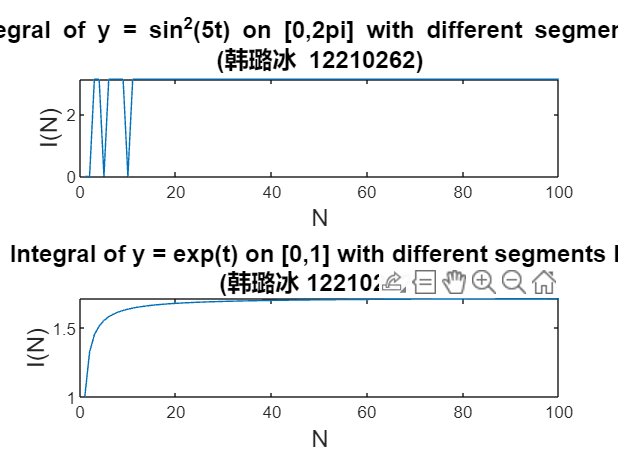

%1.3.3
figure
N=1:100;
I=zeros(1,100);
J=zeros(1,100);
for n=1:100
    I(n)=integral1(n);
    J(n)=integral2(n);
end
subplot(2,1,1)
plot(N,I)
xlabel('N','FontSize',12);%绘出x轴标注
ylabel('I(N)','FontSize',12);%绘出y轴标注
title({'Integral of y = sin^2(5t) on [0,2pi] with different segments N','(韩璐冰 12210262)'},'Fontsize',12,'FontWeight','bold');%绘出图形标题
subplot(2,1,2)
plot(N,J)
xlabel('N','FontSize',12);%绘出x轴标注
ylabel('I(N)','FontSize',12);%绘出y轴标注
title({'Integral of y = exp(t) on [0,1] with different segments N','(韩璐冰 12210262)'},'Fontsize',12,'FontWeight','bold');%绘出图形标题

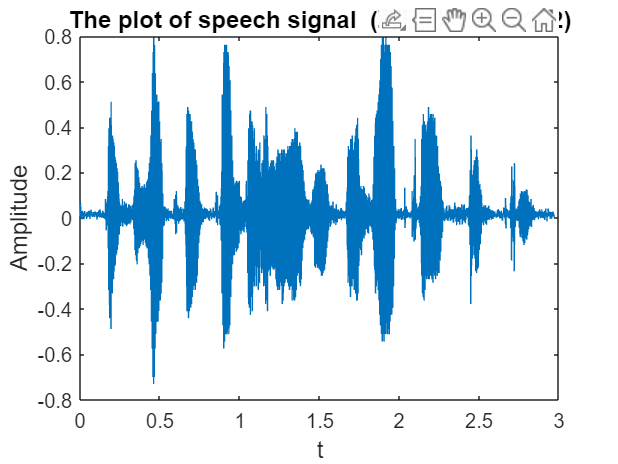

%1.4
figure
[x,fs]=audioread('speech.au');
t=0:1/fs:(length(x)-1)/fs; 
plot(t,x);
sound(x);
xlabel('t','FontSize',12);%绘出x轴标注
ylabel('Amplitude','FontSize',12);%绘出y轴标注
title('The plot of speech signal  (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题

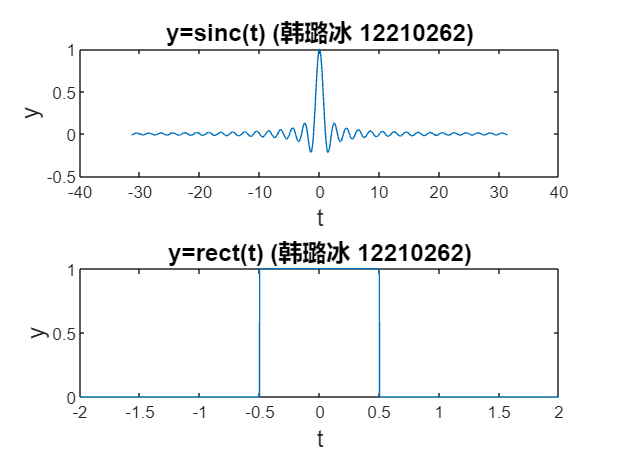

%1.5
figure
t1=-10*pi:0.05:10*pi;
y1=sinc(t1);
subplot(2,1,1);
plot(t1,y1);
xlabel('t','FontSize',12);%绘出x轴标注
ylabel('y','FontSize',12);%绘出y轴标注
title('y=sinc(t) (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题
t2=-2:0.001:2;
y2=(abs(t2)<=0.5);
subplot(2,1,2);
plot(t2,y2);
xlabel('t','FontSize',12);%绘出x轴标注
ylabel('y','FontSize',12);%绘出y轴标注
title('y=rect(t) (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题

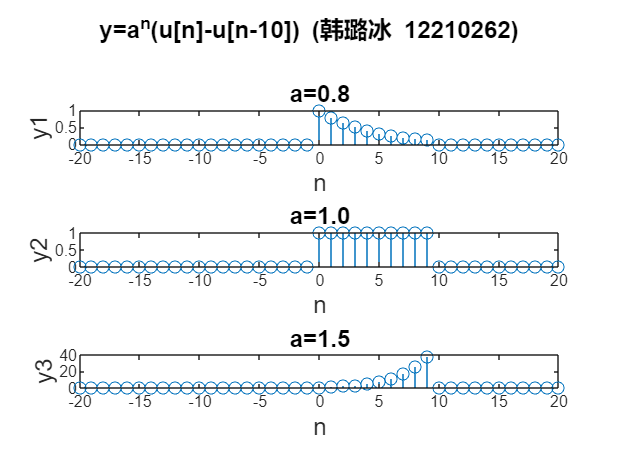


figure
n=-20:20;
y1=0.8.^n.*((n>=0)-(n>=10));
y2=1.0.^n.*((n>=0)-(n>=10));
y3=1.5.^n.*((n>=0)-(n>=10));
subplot(3,1,1);
stem(n,y1);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('y1','FontSize',12);%绘出y轴标注
title('a=0.8','Fontsize',12,'FontWeight','bold');%绘出图形标题
subplot(3,1,2);
stem(n,y2);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('y2','FontSize',12);%绘出y轴标注
title('a=1.0','Fontsize',12,'FontWeight','bold');%绘出图形标题
subplot(3,1,3);
stem(n,y3);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('y3','FontSize',12);%绘出y轴标注
title('a=1.5','Fontsize',12,'FontWeight','bold');%绘出图形标题
sgtitle('y=a^n(u[n]-u[n-10]) (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题

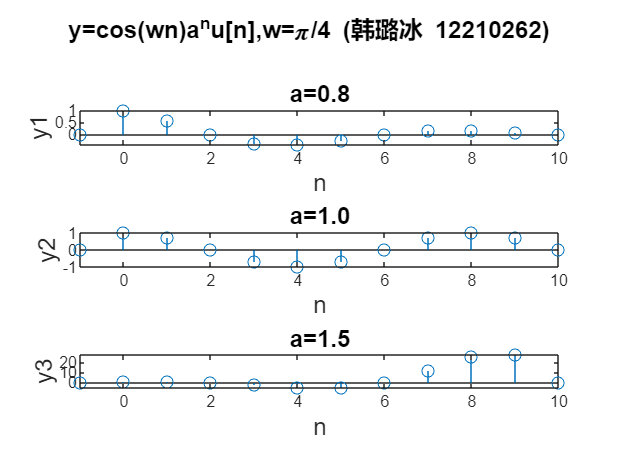

orient('tall') 

figure
n=-1:10;
y1=cos(pi/4.*n).*(0.8.^n.*(n>=0));
y2=cos(pi/4.*n).*(1.0.^n.*(n>=0));
y3=cos(pi/4.*n).*(1.5.^n.*(n>=0));
subplot(3,1,1);
stem(n,y1);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('y1','FontSize',12);%绘出y轴标注
title('a=0.8','Fontsize',12,'FontWeight','bold');%绘出图形标题
xlim([-1,10]);
subplot(3,1,2);
stem(n,y2);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('y2','FontSize',12);%绘出y轴标注
title('a=1.0','Fontsize',12,'FontWeight','bold');%绘出图形标题
xlim([-1,10]);
subplot(3,1,3);
stem(n,y3);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('y3','FontSize',12);%绘出y轴标注
title('a=1.5','Fontsize',12,'FontWeight','bold');%绘出图形标题
xlim([-1,10]);
sgtitle('y=cos(wn)a^nu[n],w=\pi/4 (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题

orient('tall') 

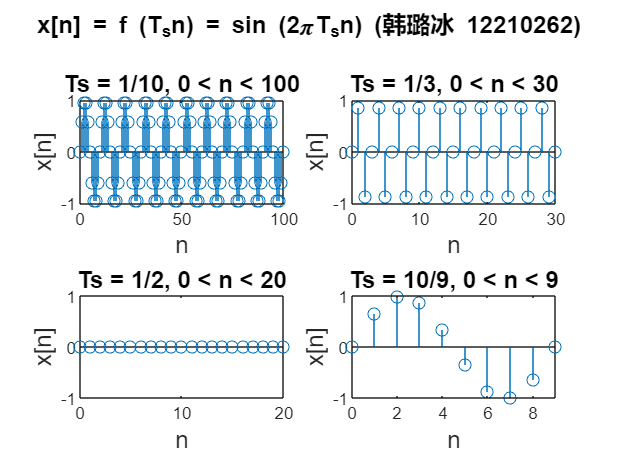

%1.6
figure
Ts1=1/10;
n1=0:100;
x1=sin(2*pi*Ts1*n1);
subplot(2,2,1);
stem(n1,x1);
axis([0,100,-1,1]);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('x[n]','FontSize',12);%绘出y轴标注
title('Ts = 1/10, 0 < n < 100','Fontsize',12,'FontWeight','bold');%绘出图形标题

Ts2=1/3;
n2=0:30;
x2=sin(2*pi*Ts2*n2);
subplot(2,2,2);
stem(n2,x2);
axis([0,30,-1,1]);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('x[n]','FontSize',12);%绘出y轴标注
title('Ts = 1/3, 0 < n < 30','Fontsize',12,'FontWeight','bold');%绘出图形标题

Ts3=1/2;
n3=0:20;
x3=sin(2*pi*Ts3*n3);
subplot(2,2,3);
stem(n3,x3);
axis([0,20,-1,1]);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('x[n]','FontSize',12);%绘出y轴标注
title('Ts = 1/2, 0 < n < 20','Fontsize',12,'FontWeight','bold');%绘出图形标题

Ts4=10/9;
n4=0:9;
x4=sin(2*pi*Ts4*n4);
subplot(2,2,4);
stem(n4,x4);
axis([0,9,-1,1]);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('x[n]','FontSize',12);%绘出y轴标注
title('Ts = 10/9, 0 < n < 9','Fontsize',12,'FontWeight','bold');%绘出图形标题
sgtitle('x[n] = f (T_sn) = sin (2\piT_sn) (韩璐冰 12210262)','Fontsize',12,'FontWeight','bold');%绘出图形标题

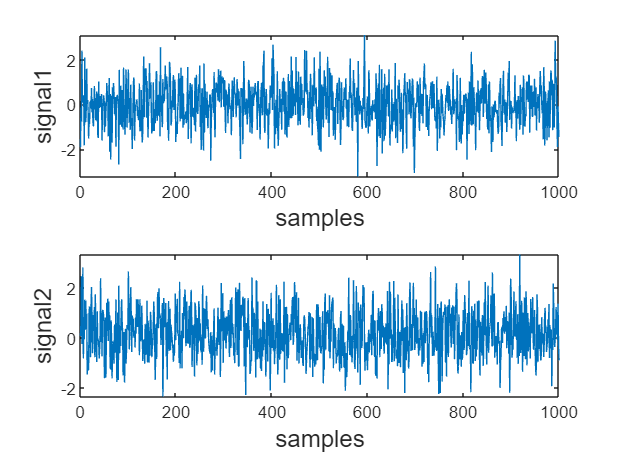

%1.7
s1=randn(1,1000);
s2=randn(1,1000)+0.2;
figure
subplot(2,1,1);
plot(s1);
xlabel('samples','FontSize',12);%绘出x轴标注
ylabel('signal1','FontSize',12);%绘出y轴标注

subplot(2,1,2);
plot(s2);
xlabel('samples','FontSize',12);%绘出x轴标注
ylabel('signal2','FontSize',12);%绘出y轴标注

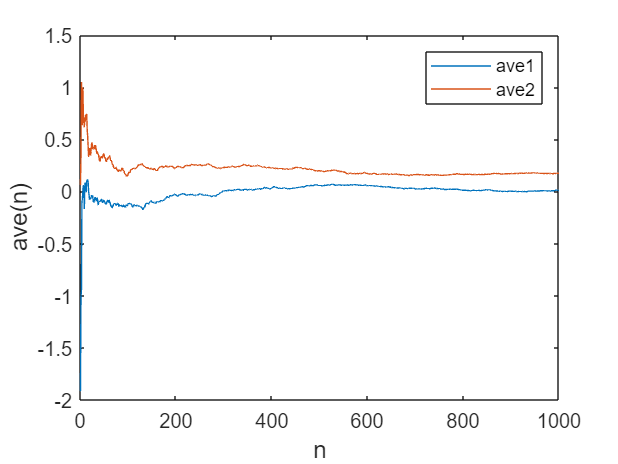


ave1=zeros(1,1000);
ave2=zeros(1,1000);
for n=1:1000
    ave1(n)=sum(s1(1,1:n))/n;
    ave2(n)=sum(s2(1,1:n))/n;
end
figure
n=1:1000;
plot(n,ave1,n,ave2);
xlabel('n','FontSize',12);%绘出x轴标注
ylabel('ave(n)','FontSize',12);%绘出y轴标注
legend('ave1','ave2');

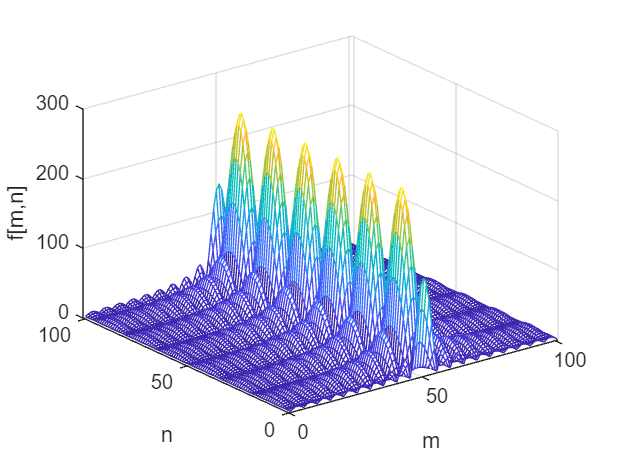

%1.8
figure
[m,n]=meshgrid(-50:1:50,-50:1:50);
f=255*abs(sinc(0.2*m).*sin(0.2*n));
mesh(f);
xlabel('m');
ylabel('n');
zlabel('f[m,n]')

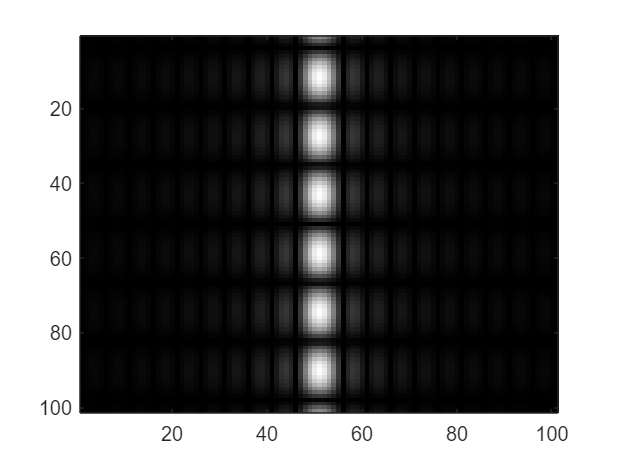

figure
image(f);
colormap(gray(256));